# Homework 8: Mie Scattering

## Scattering from canonical shapes: Mie theory

### Part 1

Review the document "Scattering from canonical shapes: Mie Theory" which contains the derivation of the two-dimensional (2D) problem of the TE-polarized plane wave scattering from a dielectric cylinder of radius *a* and material parameters $\left.{\left(\varepsilon \right.}_d ,\mu_d \right)$ immersed in a homogeneous medium with material parameters $\left.{\left(\varepsilon \right.}_m ,\mu_m \right)$. This derives the analytical expressions for (1) Mie scattering coefficients; (2) Internal and external fields; (3) Far-field scattering pattern; (4) Scattering cross-section; (5) Characteristic equation for the natural frequencies of the circular-cylinder eigenmodes.

#### *(a) What is a "scattering cross section" in Mie scattering? Give a thorough explanation as if you were teaching it to a classmate. What different characteristics of a scattering cross section might you look at to learn about a material or design an application?*

The scattering cross section is essentially the "target area" the particle presents to that light. Even though a particle has a physical size (like its radius), the cross section isn't necessarily equal to that physical area. It’s an effective area that represents how much light the particle "intercepts" and redirects. If a particle has a large scattering cross section, it’s very "visible" to the light; if it’s small, the light mostly passes by as if the particle weren't there.

If you’re designing a sensor or studying a new material, you’d analyze these specific traits of the cross section:

- **Extinction vs. Scattering: **You look at the ratio between light that is scattered (bounced) and light that is absorbed (turned into heat). For a reflective coating, you want high scattering; for a solar thermal collector, you want high absorption.

- **Wavelength Sensitivity (Spectra): **You check how the cross section changes with color. Some particles have "resonances" where the cross section spikes at a specific wavelength. This is how we design biosensors—if a target molecule attaches to a particle, the resonance shifts, and the color change tells us the molecule is present.

- **Angular Distribution (Phase Function): **Does the cross section mostly scatter light forward or backward? Forward scattering is vital for designing optical fibers or communication through fog. Backscattering is the bread and butter of Lidar (laser radar) used in self-driving cars to "see" objects.

- **Size Parameter:** We look at the ratio of the particle size to the wavelength. By tuning this, you can create "structural color"—making something look a certain color (like a butterfly wing) without using any actual pigment.

### Part 2

Write the function `scatteringCross.m` to calculate the Mie scattering cross-section (assume $\mu_m =1$, $\mu_d =1$). *Pay attention to the Bessel, *$J_m$* , and Hankel, *${H_m }^{\left(1\right)}$* , functions and their derivatives (which are designated with *${J_m }^{\prime }$* and *${H_m^{\left(1\right)} }^{\prime }$*).*

### Part 3

Write the function `scatteringField.m` for calculation of the near-field distributions (assume $\mu_m =1$, $\mu_d =1$).

### Part 4

Plot the scattering cross-sections as a function of wavelength in the range from 300 to 700 nm for two test problems ($\mu_m =1$, $\mu_d =1$): 

(a) Loss-less dielectric cylinder with $a=300\;\textrm{nm}$, $\varepsilon_d =4$ surrounded by  $\varepsilon_m =1$; 

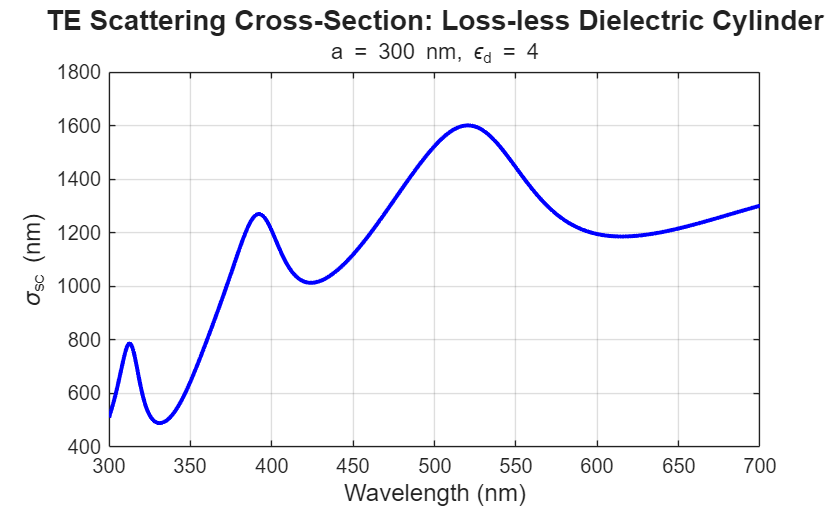

% Case 1 Scattering Cross-section ***************************
% parameters for Test Case (a)
a = 300e-9;         % Diameter [m]
epsilon_d = 4;      % Permittivity of cylinder
epsilon_m = 1;      % Permittivity of medium
mu_d = 1;           % Permeability of cylinder
mu_m = 1;           % Permeability of medium

% Wavelength range [nm]
wavelength_nm = linspace(300, 700, 400);
sigma_sc_vals = zeros(size(wavelength_nm));

% Calculate sigma_sc for each wavelength
for i = 1:length(wavelength_nm)
    % lambda in meters
    lambda = wavelength_nm(i) * 1e-9;
    
    % Angular frequency omega = 2*pi*c / lambda
    c = 3e8;
    omega = (2 * pi * c) / lambda;
    
    % Call your function
    sigma_sc_vals(i) = scatteringCross(omega, a, epsilon_m, epsilon_d, mu_m, mu_d);
end

% Plotting
figure('Color', 'w');
plot(wavelength_nm, sigma_sc_vals * 1e9, 'b-', 'LineWidth', 2); % scale to nm for visibility
grid on;
xlabel('Wavelength (nm)', 'FontSize', 12);
ylabel('\sigma_{sc} (nm)', 'FontSize', 12);
title('TE Scattering Cross-Section: Loss-less Dielectric Cylinder', 'FontSize', 14);
subtitle(sprintf('a = %d nm, \\epsilon_d = %d', a*1e9, epsilon_d));

% Optional: Set axis limits for better focus
xlim([300 700]);

(b) Silver nanocylinder with *a *= 30 nm and a complex dielectric permittivity given by the Drude formula with the same parameters from the SPP problem sets (HW 6), surrounded by  $\varepsilon_m =1$

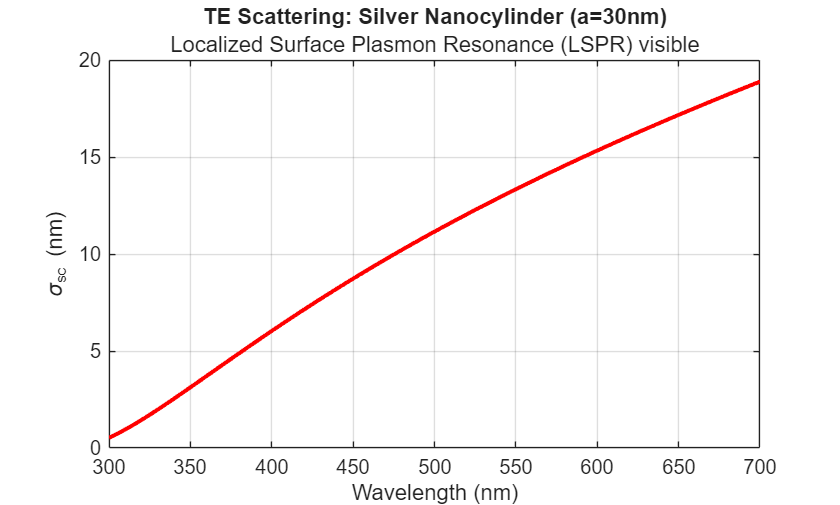

% Case 2 Scattering Cross-section ***************************

% Physical constants
c = 3e8;                % [m/s]
hbar = 6.582119e-16;    % [eV*s]

% Drude Parameters for Silver (Typical HW 6 values)
eps_inf = 5;            % High-frequency limit permittivity
wp_ev = 9.0;            % Plasma frequency [eV]
gamma_ev = 0.02;        % Damping constant [eV]

% Cylinder parameters
a = 30e-9;              % Diameter [m]
eps_m = 1;              % Surrounding medium (air)
mu_m = 1; mu_d = 1;     % Permeability

% Wavelength range [nm]
lambda_nm = linspace(300, 700, 500);
sigma_sc = zeros(size(lambda_nm));

for i = 1:length(lambda_nm)
    lam = lambda_nm(i) * 1e-9;
    omega = (2 * pi * c) / lam;
    omega_ev = hbar * omega; % Convert rad/s to eV
    
    % Drude complex permittivity
    eps_d = eps_inf - (wp_ev^2) / (omega_ev^2 + 1i * gamma_ev * omega_ev);
    
    % Calculate TE scattering cross section (using your previously defined function)
    sigma_sc(i) = scatteringCross(omega, a, eps_m, eps_d, mu_m, mu_d);
end

% Plotting the results
figure('Color', 'w');
plot(lambda_nm, sigma_sc * 1e9, 'r', 'LineWidth', 2);
grid on;
xlabel('Wavelength (nm)');
ylabel('\sigma_{sc} (nm)');
title('TE Scattering: Silver Nanocylinder (a=30nm)');
subtitle('Localized Surface Plasmon Resonance (LSPR) visible');

## Part 5

Plot the near-field distributions of the $H_z$ component at the frequencies corresponding to the highest resonance peak in the scattering cross-section for each case (you will have 1 field distribution each for case 1 and 2). We recommend using a function like contourf() to plot the field.

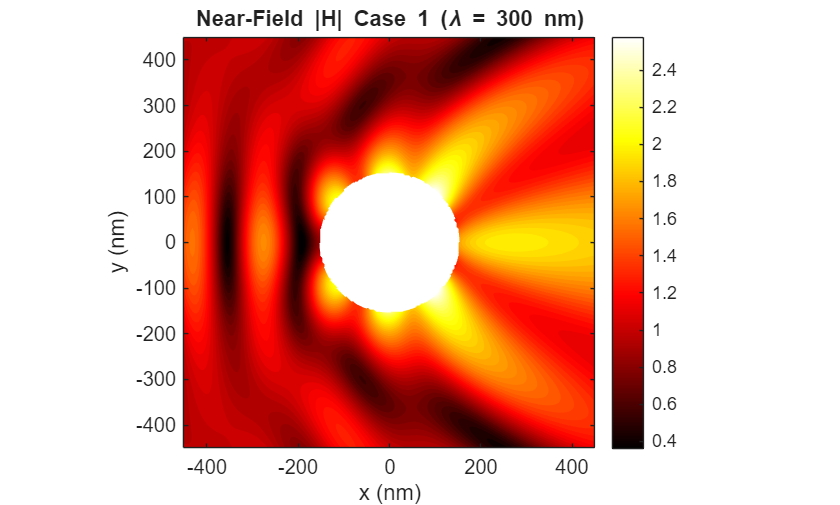

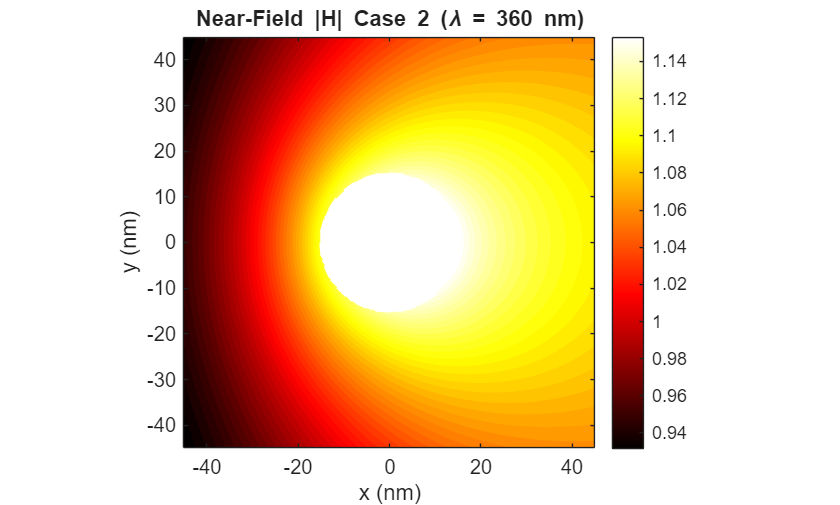

% Case 1 Scattering Field ***************************

% --- Setup Parameters ---
c = 3e8; hbar = 6.582119e-16;
lambda_peaks = [300, 360]; % Peak wavelengths in nm (Replace with values from your sigma_sc plots)
diameters = [300e-9, 30e-9];
eps_ds = {4, 'drude'}; % Case 1: constant, Case 2: Drude

% Spatial Grid (twice the cylinder diameter)
N_grid = 200;

for case_idx = 1:2
    a = diameters(case_idx);
    R = a/2;
    lambda = lambda_peaks(case_idx) * 1e-9;
    omega = (2*pi*c)/lambda;
    
    % Determine Permittivity
    if ischar(eps_ds{case_idx}) % Case 2: Silver
        omega_ev = hbar * omega;
        eps_val = 5 - (9.0^2) / (omega_ev^2 + 1i * 0.02 * omega_ev);
    else % Case 1: Dielectric
        eps_val = eps_ds{case_idx};
    end
    
    % Create Grid
    limit = 1.5 * a;
    [X, Y] = meshgrid(linspace(-limit, limit, N_grid));
    [PHI, R_grid] = cart2pol(X, Y);
    H_total = zeros(size(X));
    
    % Calculate Field at each point
    % Using a vectorized approach or loop calling your scatteringField function
    for row = 1:N_grid
        for col = 1:N_grid
            r_val = R_grid(row, col);
            phi_val = PHI(row, col);
            
            % Incident Field: exp(i*k*x)
            k_m = (omega/c);
            H_inc = exp(1i * k_m * X(row, col));
            
            if r_val > R
                % Use your scatteredField function for external points
                H_s = scatteringField(r_val, phi_val, omega, a, 1, eps_val, 1, 1);
                H_total(row, col) = H_inc + H_s;
            else
                % Internal field calculation (Optional: set to 0 or use internal Bessel expansion)
                H_total(row, col) = NaN; 
            end
        end
    end
    
    % --- Plotting ---
    figure('Color', 'w');
    contourf(X*1e9, Y*1e9, abs(H_total), 50, 'LineColor', 'none');
    hold on;
    % Draw cylinder boundary
    theta = linspace(0, 2*pi, 100);
    plot(R*1e9*cos(theta), R*1e9*sin(theta), 'w--', 'LineWidth', 1.5);
    
    colormap('hot'); colorbar;
    axis equal; xlabel('x (nm)'); ylabel('y (nm)');
    title(sprintf('Near-Field |H| Case %d (\\lambda = %d nm)', case_idx, lambda_peaks(case_idx)));
end